# Virtual Environments Examples

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/3.0_Virtual_environments.html)

### Example 29 - Object space

Define house object

Vhouse = [-0.5, 0.5, 0.5, -0.5, -0.5, 0.5, 0.5, -0.5, 0, 0 ;
          -1,  -1,   1,    1,   -1,  -1,   1,    1,  -1, 1 ;
           0,   0,   0,    0,    1,   1,   1,    1,   2, 2 ;
           1,   1,   1,    1,    1,   1,   1,    1,   1, 1];

Fhouse = [4, 3,  2,  1, 1 ;    % base
          1, 2,  6,  9, 5 ;    % front wall
          2, 3,  7,  6, 6 ;    % right wall
          3, 4,  8, 10, 7 ;    % back wall
          1, 5,  8,  4, 4 ;    % left wall
          6, 7, 10,  9, 9 ;    % right roof
          5, 9, 10,  8, 8 ];   % left roof

Plot object space

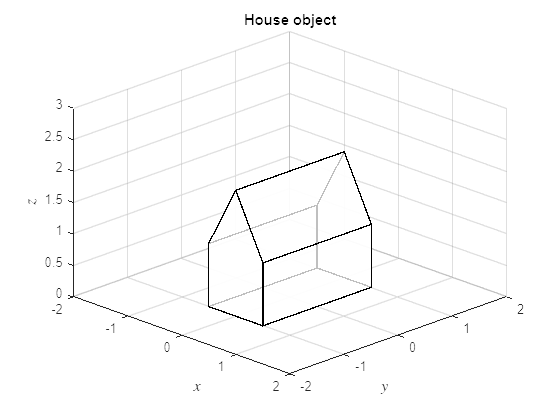

figure
patch("Vertices", Vhouse(1:3,:)', "Faces", Fhouse, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
title('House object')
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$y$", "Interpreter", "latex", "FontSize", 12)
zlabel("$z$", "Interpreter", "latex", "FontSize", 12)
view(45, 30)
axis([-2, 2, -2, 2, 0, 3])
grid on

### Example 30 - World space

Define cube object

Vcube = [ -1,  1,  1, -1, -1,  1, 1, -1 ;
          -1, -1,  1,  1, -1, -1, 1,  1 ;
          -1, -1, -1, -1,  1,  1, 1,  1 ;
           1,  1,  1,  1,  1,  1, 1,  1 ];

Fcube = [ 1, 4, 3, 2, 2 ;
          1, 2, 6, 5, 5 ; 
          2, 3, 7, 6, 6 ;
          3, 4, 8, 7, 7 ;
          4, 1, 5, 8, 8 ;
          5, 6, 7, 8, 8 ];

Define object types, positions, scaling and rotation angles

objecs = [ 2, 2, 1 ];           % object types (1 = cube, 2 = house)
pos = [ 3,   3.5, 0 ;           % object positions (x, y, z)
        3,   1.5, 0 ;
        1.5, 1.5, 1.5 ];
scale = [ 1,   1,   1 ;         % object scales (sx, sy, sz)
          1,   1,   1 ;
          0.5, 0.5, 1.5 ];
angle = [ 0, 0, pi/2 ;          % object angles (theta_x, theta_y, theta_z)
          0, 0, pi/2 ;
          0, 0, 0 ];

Define transformation matrices

T = @(t) [ 1, 0, 0, t(1) ; 
           0, 1, 0, t(2) ; 
           0, 0, 1, t(3) ; 
           0, 0, 0, 1 ];

S = @(s) [ s(1), 0,    0,    0 ;  
           0,    s(2), 0,    0 ; 
           0,    0,    s(3), 0 ; 
           0,    0,    0,    1 ];

Rx = @(theta) [ 1, 0, 0, 0 ;
                0, cos(theta), -sin(theta), 0 ;
                0, sin(theta), cos(theta), 0 ;
                0, 0, 0, 1];

Ry = @(theta) [ cos(theta), 0, sin(theta), 0 ;
                0, 1, 0, 0 ;
                -sin(theta), 0, cos(theta), 0 ;
                0, 0, 0, 1 ];

Rz = @(theta) [ cos(theta), -sin(theta), 0, 0 ;
                sin(theta), cos(theta), 0, 0 ;
                0,           0,         1, 0 ;
                0,           0,         0, 1 ];

Add objects to world space

% Loop through objects
Vworld = [];
Fworld = [];
for i = 1 : 3

    % Get object vertices and face array
    if objecs(i) == 1  % cube object
        Vobj = Vcube;
        Fobj = Fcube + size(Vworld,2);  % add number of vertices in the world space to F
    elseif objecs(i) == 2  % house object
        Vobj = Vhouse;
        Fobj = Fhouse + size(Vworld,2);
    end

    % Transform object
    Vobj = T(pos(i,:)) * Rx(angle(i,1)) * Ry(angle(i,2)) * Rz(angle(i,3)) * S(scale(i,:)) * Vobj;

    % Add object to world space
    Vworld = [Vworld, Vobj];
    Fworld = [Fworld ; Fobj];
end

Plot world space

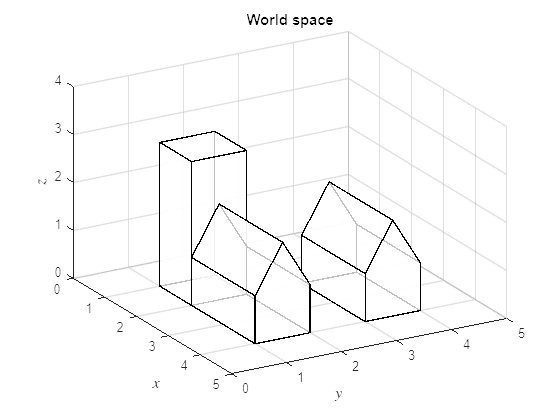

figure
patch("Vertices", Vworld(1:3,:)', "Faces", Fworld, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
title('World space')
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$y$", "Interpreter", "latex", "FontSize", 12)
zlabel("$z$", "Interpreter", "latex", "FontSize", 12)
view(60, 30)
axis([0, 5, 0, 5, 0, 4])
grid on

### Example 31 - Camera space

Define camera position and centre of view

p = [5 , 5 , 1.75];
c = [4 , 4 , 1.5];
k = [0 , 0 , 1];

Calculate alignment matrix

w = (p - c) / norm(p - c);
u = cross(k, w) / norm(cross(k, w));
v = cross(w, u);
A = [ u, -dot(p, u) ; 
      v, -dot(p, v) ;
      w, -dot(p, w) ;
      0, 0, 0, 1 ];

Align world space to the camera space

Vcamera = A * Vworld;

Plot camera space

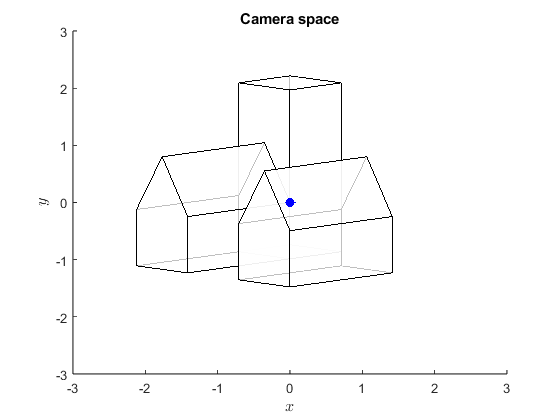

figure
h1 = axes;
patch("Vertices", Vcamera([1,3,2],:)', "Faces", Fworld, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
hold on
plot3(0, 0, 0, "bo", MarkerFaceColor="b")
quiver3(0, 0, 0, 0, -1, 0, "b", MaxHeadSize=1)
hold off
set(h1, "Ydir", "reverse")  % reverse z axis so that it matches the right-hand rule
title('Camera space')
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$z$", "Interpreter", "latex", "FontSize", 12)
zlabel("$y$", "Interpreter", "latex", "FontSize", 12)
view(0,0)
axis([-3, 3, -6, 0, -3, 3])

### Exercise 32 - Screen space

Define projection parameters

near = 1;
far = 5;
fov = pi/2;
aspect = 4/3;

Calculate projection matrix

r = near * tan(fov / 2);
t = r / aspect;
P = [-near / r, 0, 0, 0 ;
     0, -near / t, 0, 0 ;
     0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
     0, 0, 1, 0 ]

P =    -1.0000         0         0         0
         0   -1.3333         0         0
         0         0   -1.5000   -2.5000
         0         0    1.0000         0


Calculate screen space co-ordinates

Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

Plot camera space with viewing frustum

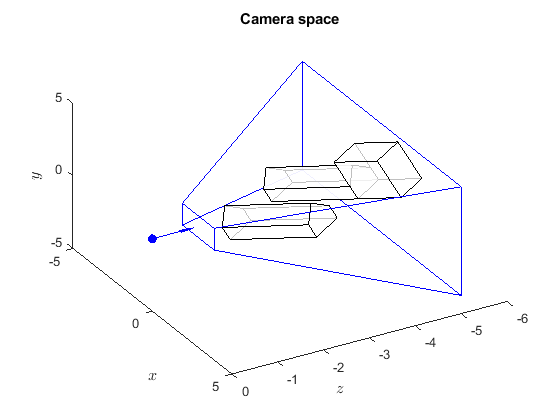

rfar = far * tan(fov / 2);
tfar = rfar / aspect;
Vfrustum = [ -r,     r,     rfar, -rfar, -r,     r,     rfar, -rfar ;
             -t,    -t,    -tfar, -tfar,  t,     t,     tfar,  tfar ;
             -near, -near, -far,  -far,  -near, -near, -far,  -far  ;
              1,     1,     1,     1,     1,     1,     1,     1    ];

figure()
h1 = axes;
patch("Vertices", Vcamera([1,3,2],:)', "Faces", Fworld, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
patch("Vertices", Vfrustum([1,3,2],:)', "Faces", Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0,0,0,"bo",MarkerFaceColor="b")
quiver3(0,0,0,0,-1,0, "b", MaxHeadSize=1)
hold off
title('Camera space')
xlabel("$x$", "Interpreter", "latex", "FontSize", 12)
ylabel("$z$", "Interpreter", "latex", "FontSize", 12)
zlabel("$y$", "Interpreter", "latex", "FontSize", 12)
set(h1, "Ydir", "reverse")
view(60,45)
axis([-5, 5, -6, 0, -5, 5])

Plot screen space

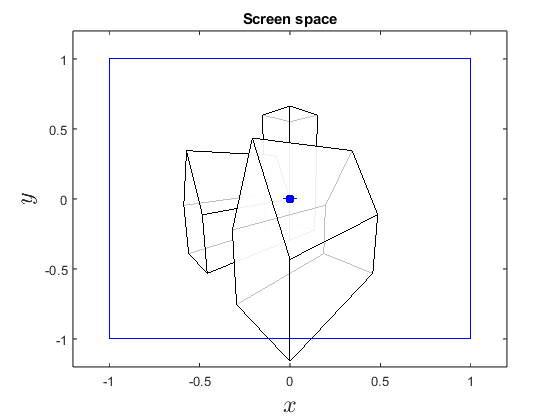

Vfrustum = P * Vfrustum;
Vfrustum = Vfrustum ./ Vfrustum(4,:);

% Plot screen space viewed from the side
figure()
h1 = axes;
patch("Vertices", Vscreen([1,3,2],:)', "Faces", Fworld, FaceColor="w", FaceAlpha=0.75, LineWidth=1)
patch("Vertices", Vfrustum(1:3,:)', "Faces", Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0, 1, 0,"bo",MarkerFaceColor="b")
quiver3(0, 1, 0, 0, -0.5, 0, "b", MaxHeadSize=1)
hold off
title('Screen space')
xlabel("$x$", "Interpreter", "latex", "FontSize", 18)
ylabel("$z$", "Interpreter", "latex", "FontSize", 18)
zlabel("$y$", "Interpreter", "latex", "FontSize", 18)
set(h1, "Ydir", "reverse")  % reverse z axis so that it matches the right-hand rule
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box

% exportgraphics(gcf,'../images/screen_space_example_3.png', Resolution=300)